# Effect of destroying head direction correlations with other noise correlations on position encoding accuracy

In the open field experiment where the stimuli and actions are much less controlled, the shuffled data contained less information than the real data, contrary to what we find in the linear track experiment where both position and direction of motion are possible to control. As an intermediate, we consider the case of treating head direction as a latent variable and removing its influence using the trial shuffle.

ntype = 'events_transients';

## PLS plots

d = SessManager.load_special('Mouse2022', ntype);
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_shuf_nohead = shuffle(X, ceil(ks/2));
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
X_shuf_nohead_z = zscore(X_shuf_nohead);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);

XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

XS_hs = (X_shuf_nohead_z - mean(X_shuf_nohead_z)) * stats.W;
origin_hs = -mean(X_shuf_nohead_z) * stats.W;

Using one session from Mouse2022, showing real data:

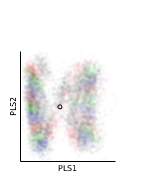

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

And shuffled data:

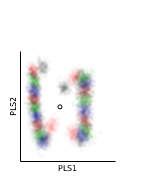

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

And data with head direction shuffled as well:

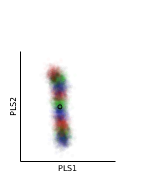

figure;
scatter(XS_hs(:,1), XS_hs(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_hs(1), origin_hs(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);

## Shuffled decoding without head direction

d = SessManager.load_special('Mouse2022', ntype);

alg = my_algs('lda');

n_cells = size(d.data_tensor,1);

n_neu = unique([1 (30:30:n_cells) n_cells]);
NN = numel(n_neu);

n_reps = 16;

[mse,mse_s,mse_h,mse_hs] = deal(zeros(n_reps, NN));

WaitMessage = parfor_wait(n_reps*NN);
parfor r_i = 1:n_reps
    for i = 1:NN
        
        res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, d.opt.bin_width, alg, n_neu(i), [], false);
        res_h = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, d.opt.bin_width, alg, n_neu(i), [], true);
        
        mse(r_i, i) = res.MSE.unshuffled;
        mse_s(r_i, i) = res.MSE.shuffled;
        
        mse_h(r_i, i) = res_h.MSE.unshuffled;
        mse_hs(r_i, i) = res_h.MSE.shuffled;
        
        WaitMessage.Send;
    end
end

figure;
mdl = ep_mdl(n_neu, 1./mse, 'b')

mdl =      General model:
     mdl(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001154  (0.0001078, 0.0001229)
       N =       555.9  (463.6, 648.1)

hold on;
mdl_s = ep_mdl(n_neu, 1./mse_s, 'r')

mdl_s =      General model:
     mdl_s(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0002566  (0.0002366, 0.0002766)
       N =        8190  (-5532, 2.191e+04)


mdl_h = ep_mdl(n_neu, 1./mse_h, 'g')

mdl_h =      General model:
     mdl_h(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001062  (9.552e-05, 0.0001169)
       N =       566.9  (421.2, 712.6)

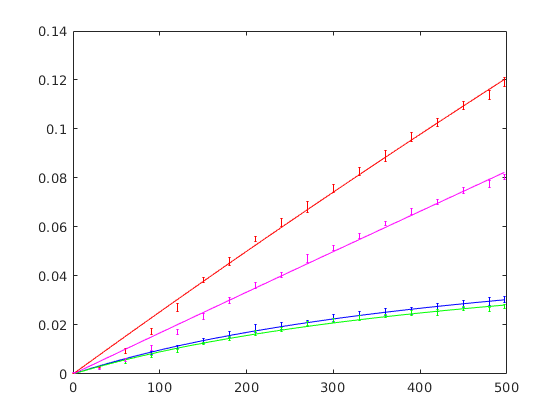

mdl_hs =      General model:
     mdl_hs(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001681  (0.0001527, 0.0001834)
       N =   3.331e+04  (-2.214e+05, 2.881e+05)

hold on;
mdl_hs = ep_mdl(n_neu, 1./mse_hs, 'm')

alg = my_algs('ecoclin');

n_cells = size(d.data_tensor,1);

d_neu = 30;
n_neu = unique([(d_neu:d_neu:n_cells) n_cells]);
NN = numel(n_neu);

n_reps = 16;

[mse,mse_s,mse_h,mse_hs] = deal(zeros(n_reps, NN));

WaitMessage = parfor_wait(n_reps*NN);
parfor r_i = 1:n_reps
    for i = 1:NN
        
        res = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, d.opt.bin_width, alg, n_neu(i), [], false);
        res_h = DecodeTensor.decode_all(d.data_tensor, d.tr_dir, d.opt.bin_width, alg, n_neu(i), [], true);
        
        mse(r_i, i) = res.MSE.unshuffled;
        mse_s(r_i, i) = res.MSE.shuffled;
        
        mse_h(r_i, i) = res_h.MSE.unshuffled;
        mse_hs(r_i, i) = res_h.MSE.shuffled;
        
        WaitMessage.Send;
    end
end

figure;
mdl = ep_mdl(n_neu, 1./mse, 'b')

mdl =      General model:
     mdl(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0002153  (0.0001038, 0.0003267)
       N =       167.4  (66.97, 267.8)
       c =   -0.000964  (-0.004619, 0.002691)

hold on;
mdl_s = ep_mdl(n_neu, 1./mse_s, 'r')

mdl_s =      General model:
     mdl_s(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0002927  (0.0002311, 0.0003542)
       N =        2284  (-230.3, 4799)
       c =   -0.004128  (-0.009793, 0.001537)


mdl_h = ep_mdl(n_neu, 1./mse_h, 'g')

mdl_h =      General model:
     mdl_h(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =    0.000114  (6.302e-05, 0.000165)
       N =       358.4  (112.5, 604.3)
       c =  -0.0001228  (-0.002758, 0.002512)

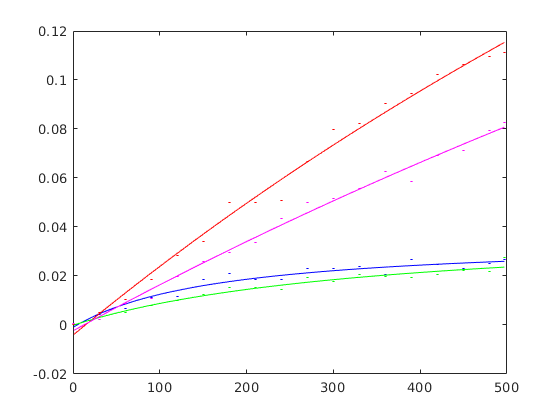

mdl_hs =      General model:
     mdl_hs(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001938  (0.0001531, 0.0002345)
       N =        3128  (-1365, 7620)
       c =   -0.002375  (-0.006275, 0.001524)

hold on;
mdl_hs = ep_mdl(n_neu, 1./mse_hs, 'm')

function [mdl, gof] = ep_mdl(n, m, varargin)
ep(n, m, varargin{:});
[mdl, gof] = createFit_intercept(n, mean(m,1));
hold on;
plot(1:max(n), mdl(1:max(n)), varargin{:});
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end

function ci = get_ci(fit_mdl, varname)
names = coeffnames(fit_mdl);
idx = find(strcmp(names, varname));
assert(numel(idx) == 1, 'Variable not found');

q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end